 PUY_st.name='PUY'; 
PUY_st.lat=45.7723;
PUY_st.lon=2.9658;
PUY_st.alt=1465;
PUY_st.env='Mt';
PUY_st.footp='Mx';


PUY_rdV1=read_betsy('PUY_2006_2017',PUY_st.name);
PUY_rd=read_betsy('PUY_2006_2018',PUY_st.name);

t=datenum([2018 01 01 00 00 00])*ones(8760,1)+{FR0030R_abs_2018.VarName1};
abs18=timetable(datetime (datevec(t)));
abs18.BaR=IT0004R.VarName3;
abs18=retime(abs18,'daily',@nanmedian);

sc18=read_nasa_ames_ebas('FR0030R.20180101000000.20190529122548.nephelometer.aerosol_light_scattering_coefficient.aerosol.1y.1h.FR04L_nephelometer_TSI_3563.FR04L_Neph.lev2.nas','\\meteoswiss.ch\mch\pay-prod\Aerosol_actris_trend\data\puy\');


%take AE16 data from import
Anne2001puydeDme.ss=Anne2001puydeDme.mm;
A2001=timetable(datetime(([Anne2001puydeDme.AAAA Anne2001puydeDme.MM Anne2001puydeDme.JJ Anne2001puydeDme.hh Anne2001puydeDme.mm Anne2001puydeDme.ss])));
A2001.BaW=Anne2001puydeDme.BC;
A2001=A2001(2:end,:);
A2001.BaW(A2001.BaW<-98)=NaN;

Anne2002puydeDme.ss=Anne2002puydeDme.mm;
A2002=timetable(datetime(([Anne2002puydeDme.AAAA Anne2002puydeDme.MM Anne2002puydeDme.JJ Anne2002puydeDme.hh Anne2002puydeDme.mm Anne2002puydeDme.ss])));
A2002.BaW=Anne2002puydeDme.BC;
A2002=A2002(2:end,:);
A2002.BaW(A2002.BaW<-98)=NaN;

Anne2003puydeDme.ss=Anne2003puydeDme.mm;
A2003=timetable(datetime(([Anne2003puydeDme.AAAA Anne2003puydeDme.MM Anne2003puydeDme.JJ Anne2003puydeDme.hh Anne2003puydeDme.mm Anne2003puydeDme.ss])));
A2003.BaW=Anne2003puydeDme.BC;
A2003=A2003(2:end,:);
A2003.BaW(A2003.BaW<-98)=NaN;

Anne2004puydeDme.ss=Anne2004puydeDme.mm;
A2004=timetable(datetime(([Anne2004puydeDme.AAAA Anne2004puydeDme.MM Anne2004puydeDme.JJ Anne2004puydeDme.hh Anne2004puydeDme.mm Anne2004puydeDme.ss])));
A2004.BaW=Anne2004puydeDme.BC;
A2004=A2004(2:end,:);
A2004.BaW(A2004.BaW<-98)=NaN;

Anne2005puydeDme.ss=Anne2005puydeDme.mm;
A2005=timetable(datetime(([Anne2005puydeDme.AAAA Anne2005puydeDme.MM Anne2005puydeDme.JJ Anne2005puydeDme.hh Anne2005puydeDme.mm Anne2005puydeDme.ss])));
A2005.BaW=Anne2005puydeDme.BC;
A2005=A2005(2:end,:);
A2005.BaW(A2005.BaW<-98)=NaN;


An2006=FR06BC(:,1:4);
An2006.Time=datetime(datevec(datenum([2006 01 01]).*ones(8760,1)+FR06BC{:,1}));
An2006.BaW=FR06BC.VarName3;
An2006.VarName1=[];
An2006.VarName2=[];
An2006.VarName3=[];
An2006.VarName4=[];
A2006=table2timetable(An2006);
A2006.BaW(A2006.BaW>98)=NaN;
A2006.BaW=A2006.BaW*1000;

An2007=FR07BC(1:8760,1:4);
An2007.Time=datetime(datevec(datenum([2007 01 01]).*ones(8760,1)+FR07BC{1:8760,1}));
An2007.BaW=FR07BC.VarName3(1:8760);
An2007.VarName1=[];
An2007.VarName2=[];
An2007.VarName3=[];
An2007.VarName4=[];
A2007=table2timetable(An2007);
A2007.BaW(A2007.BaW>98)=NaN;
A2007.BaW=A2007.BaW*1000;

Ae16=synchronize(A2001,A2002,A2003,A2004,A2005,A2006,A2007);
N=fieldnames(Ae16);
c=startsWith(N,'BaW');
NN=N(c);
% for i=1:length(NN)
% Ae16.(NN{i})(abs(Ae16.(NN{i}))>98)=NaN;
% end
Ae16.BaW=sum([Ae16.BaW_A2001 Ae16.BaW_A2002 Ae16.BaW_A2003 Ae16.BaW_A2004 Ae16.BaW_A2005 Ae16.BaW_A2006 Ae16.BaW_A2007],2,'omitnan');
indz=Ae16.BaW==0;
Ae16.BaW(indz)=NaN;
for i=1:length(NN)
Ae16.(NN{i})=[];
end
Ae16d=retime(Ae16,'daily',@nanmedian);

PUY_rdV2=timetable(datetime([an;mois;jour;heure;ones(1,length(an));ones(1,length(an))]'));
PUY_rdV2.BaG_A=BC';
PAE=timerange('2000-01-01','2006-06-22');
cte = 14625e-9/3.5;
PUY_rdV2.BaG_A=PUY_rdV2.BaG_A.*cte./660 ;
PUY_rdV2.BsB_S=TSC450';
PUY_rdV2.BsG_S=TSC550';
PUY_rdV2.BsR_S=TSC700';
PUY_rdV2.BbsB_S=BSC450';
PUY_rdV2.BbsG_S=BSC550';
PUY_rdV2.BbsR_S=BSC700';
PUY_rdV2=retime(PUY_rdV2,'daily',@nanmedian);

plotFigControl(PUY_rdV2,PUY_st.name);

datevec(PUY_rd.Time(1))

ans =         2006           1           2           0           0           0


datevec(PUY_rd.Time(end))

ans =         2019           1           1           0           0           0


prctile(PUY_rd.U_S11,[5 50 95])

ans =    10.0000   26.3000   49.0000


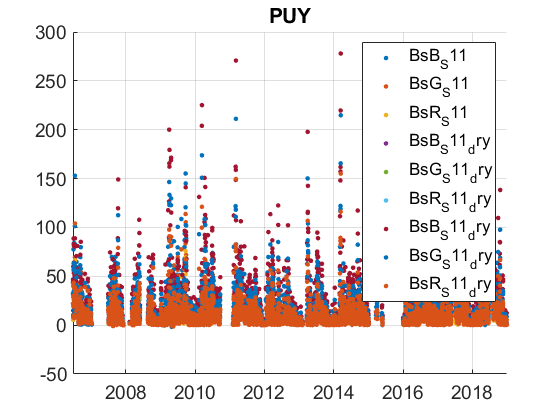

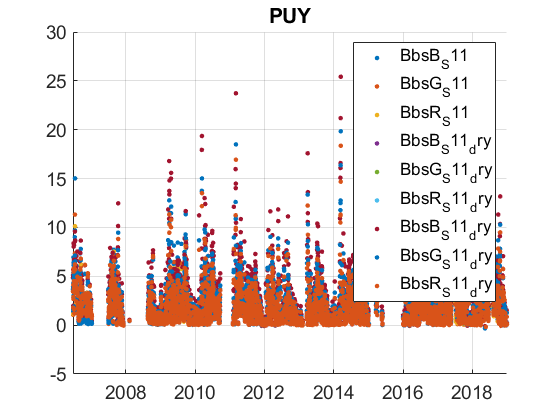

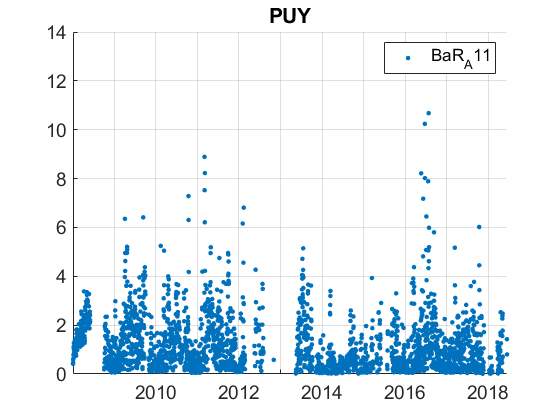

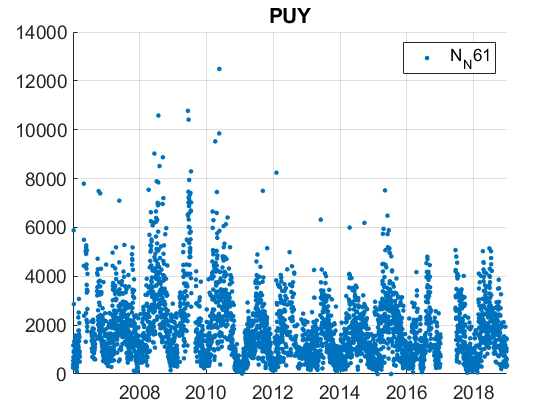

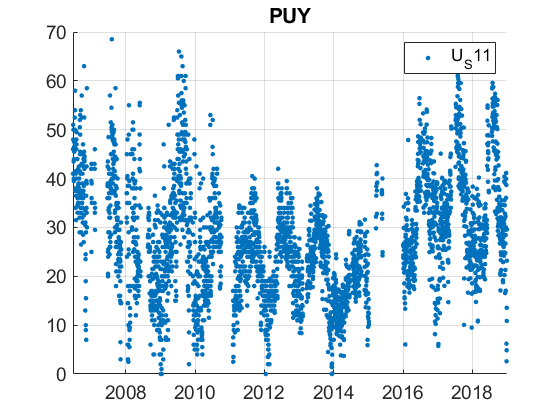

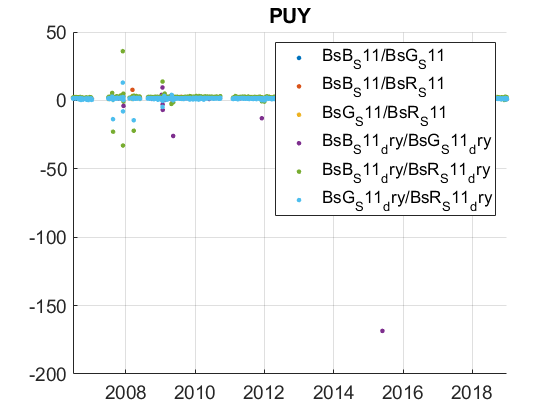

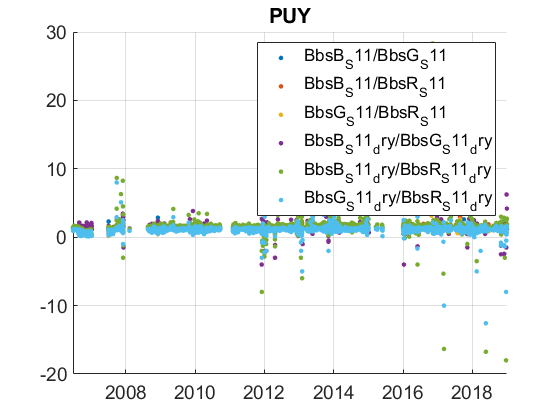

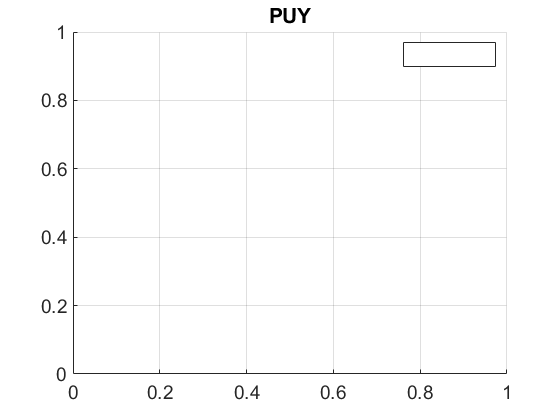

plotFigControl(PUY_rd,PUY_st.name);

% 1 size cut, ok
% sc: ok, max in summer, no negatives
% abs: 2 size cut, max in summer, no negatives


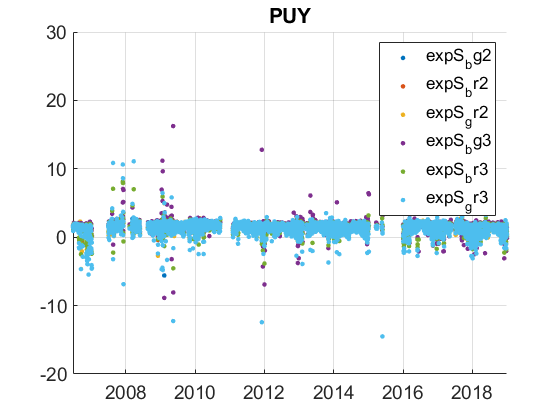

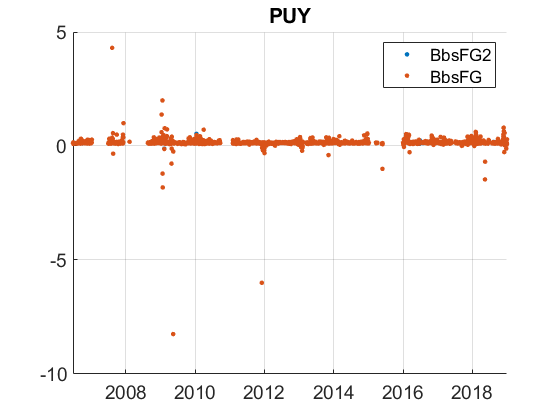

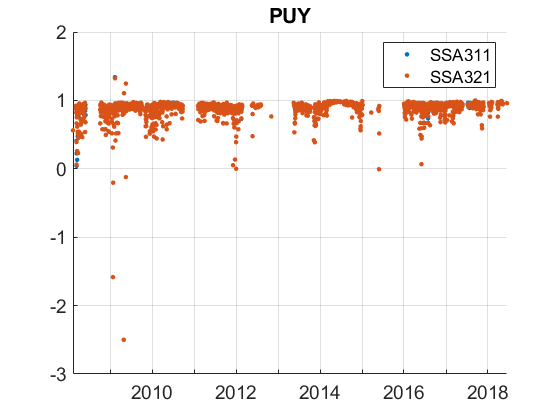

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
PUY_cal=compute_exp_SSA(PUY_rd,lambdaSC, lambdaAE);
plotFigControl_cal(PUY_cal, PUY_st.name);

%Questions:
%problems:
%sc: there is a lot of holes, are they all real ?
%bsc: strange behaviour of the Bbs ratio from November to December 2006. Do you have an explanation?
%Bsc: globally the BbsG/BbsR is very low compared to the scattering ratio with the same wavelength.

%Abs: there is hole in 2008 and 2012-2013. Are they real or due to databank ?
%abs: the first par of 2008 seems to have a different variability than the rest of the time series. What happened ?
%abs: in 2014 the SSA is too high, probably due to too low absorption. Do you have an explanation ?

%N: why are data much lower in winter 2010-2011 ?

PUY_tr=PUY_rd;
PUY_tr.y=year(PUY_tr.Time);
% begin at the beginning of a year: sc: 2009 (to have more or less entire years. scat begin in 6 March in 2008, abs 2008
%END 2018 for scat and 2017 for abs (only until June 2018
P=timerange('2009-01-01','2019-01-01');
PUY_tr=PUY_tr(P,:);


% RH> 40 before 2011 and after 2016 --> trend in RH and in scat_dry
names=fieldnames(PUY_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"Uu";"U1"]) |  contains(names,["Q";"X";"B1_";"G1_";"R1_";"B0_A";"G0_A";"R0_A"]);
N=names(c);
for i=1:length(N)
    PUY_tr.(N{i})=[];
end

%abs, end in 2017
p1=timerange('2018-01-01','2019-01-01');
PUY_tr.BaR_A11(p1)=NaN;

%abs: conversion AE16 BC en absorption

%MAAP: probleme 2008: invalider depuis quand ? soit 26 octobre soit 7
%décembre: debut en 2009
%MAAP: problème 2014: invalider 6.3 to 26.7.2014
p2=timerange('2014-03-06','2014-07-26');
PUY_tr.BaR_A11(p2)=NaN;

%correct abs for green wavelength to compute SSA
PUY_tr.BaR_A11=PUY_tr.BaR_A11.*(637/550);

PUY_cal2=compute_exp_SSA(PUY_tr,lambdaSC, lambdaAE);
PUY_tr=outerjoin(PUY_tr, PUY_cal2);

%compute trend only on G neph
PUY_tr.BsB_S11=[];
PUY_tr.BsB_S11_dry=[];
PUY_tr.BsR_S11=[];
PUY_tr.BsR_S11_dry=[];
PUY_tr.BbsB_S11=[];
PUY_tr.BbsB_S11_dry=[];
PUY_tr.BbsR_S11=[];
PUY_tr.BbsR_S11_dry=[];

% trend only on BG exp 
PUY_tr.expS_br2=[];
PUY_tr.expS_gr2=[];

PUY_tr.expS_br3=[];
PUY_tr.expS_gr3=[];

PUY_result= all_trend_STN(PUY_tr,PUY_st); 

PUY_result_D=PUY_result;
% not to confuse with dry trend, remove expS_bg3 and SSA321
PUY_result_D=PUY_result_D(startsWith(PUY_result_D.parameter,["expS_bg3","SSA321"])==0,:);